clc,clear;

The state space system is represented in the following form.


$$\begin{array}{l}
\dot{x} \;\left(t\right)=A\;x\left(t\right)+B\;u\left(t\right)\\
y\left(t\right)=C\;x\left(t\right)+D\;u\left(t\right)
\end{array}$$


That can be defined as,

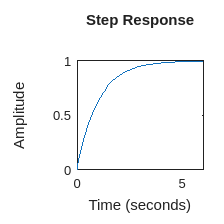

A = [1,0;-1,-1];
B = [0;1];
C = [0,1];
D = 0;
sys =  ss(A,B,C,D);
step(sys)

Conversion from Transfer function,

For the Transfer function,


$$G\left(s\right)=\frac{K}{s^2 +a\;s+b}$$


The state space matrices in Observable companion form will be represented as,


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack ;\;B=\left\lbrack \begin{array}{c}
0\\
K
\end{array}\right\rbrack ;\;C=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack ;\;D=0;$$
 

s = tf('s');
G = 0.5 / (s ^ 2 + 2 * s + 1)


G =
 
       0.5
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.


sys = ss(G);
sys_can = compreal(sys, 'o')


sys_can =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1  -2
 
  B = 
        u1
   x1    0
   x2  0.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Q_c = ctrb(sys_can);

if rank(Q_c) == size(A, 1)
  disp('The system is controllable')
else
  disp('The system is not controllable')
end

The system is controllable


%%
Q_o = obsv(sys_can);

if rank(Q_o) == size(A, 1)
  disp('The system is observable')
else
  disp('The system is not observable')
end

The system is observable



[A, B, C, D] = ssdata(sys_can);

Based on the following control law the feedback and input gain can be calculated with the following code.


$$u={-K}_1 \;x\left(t\right)+K_2 \;r\left(t\right)$$


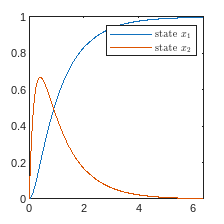

p1 = -1; p2 = -5;
K_1 = place(A, B, [p1 p2]);
A_m = A - B*K_1; % new A matrix with controller
K_2= -1/(C*inv(A_m)*B);
B_m = B*K_2; % new B matrix with reference gain
sys_cl = ss(A_m, B_m, C, D); % new closed-loop system
[y,t,x] = step(sys_cl);
plot(t,x)
legend(['state $x_1$';'state $x_2$'],'Interpreter','latex')

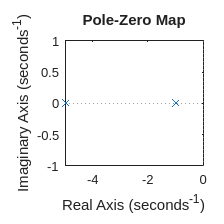

pzmap(sys_cl) % pole-zero plot


disp("The feedback gain of the system will be")

The feedback gain of the system will be


display(K_1)

K_1 =     8.0000    8.0000


display(K_2)

K_2 = 10.0000

The simulink diagram should be implemented as follows, Please ensure the observable canonical form while implementing the following configuration. In observable canonical form the A, B, C and D matrices has follwoing form,


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-b & -a
\end{array}\right\rbrack ;B=\left\lbrack \begin{array}{c}
0\\
K
\end{array}\right\rbrack ;C=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$$


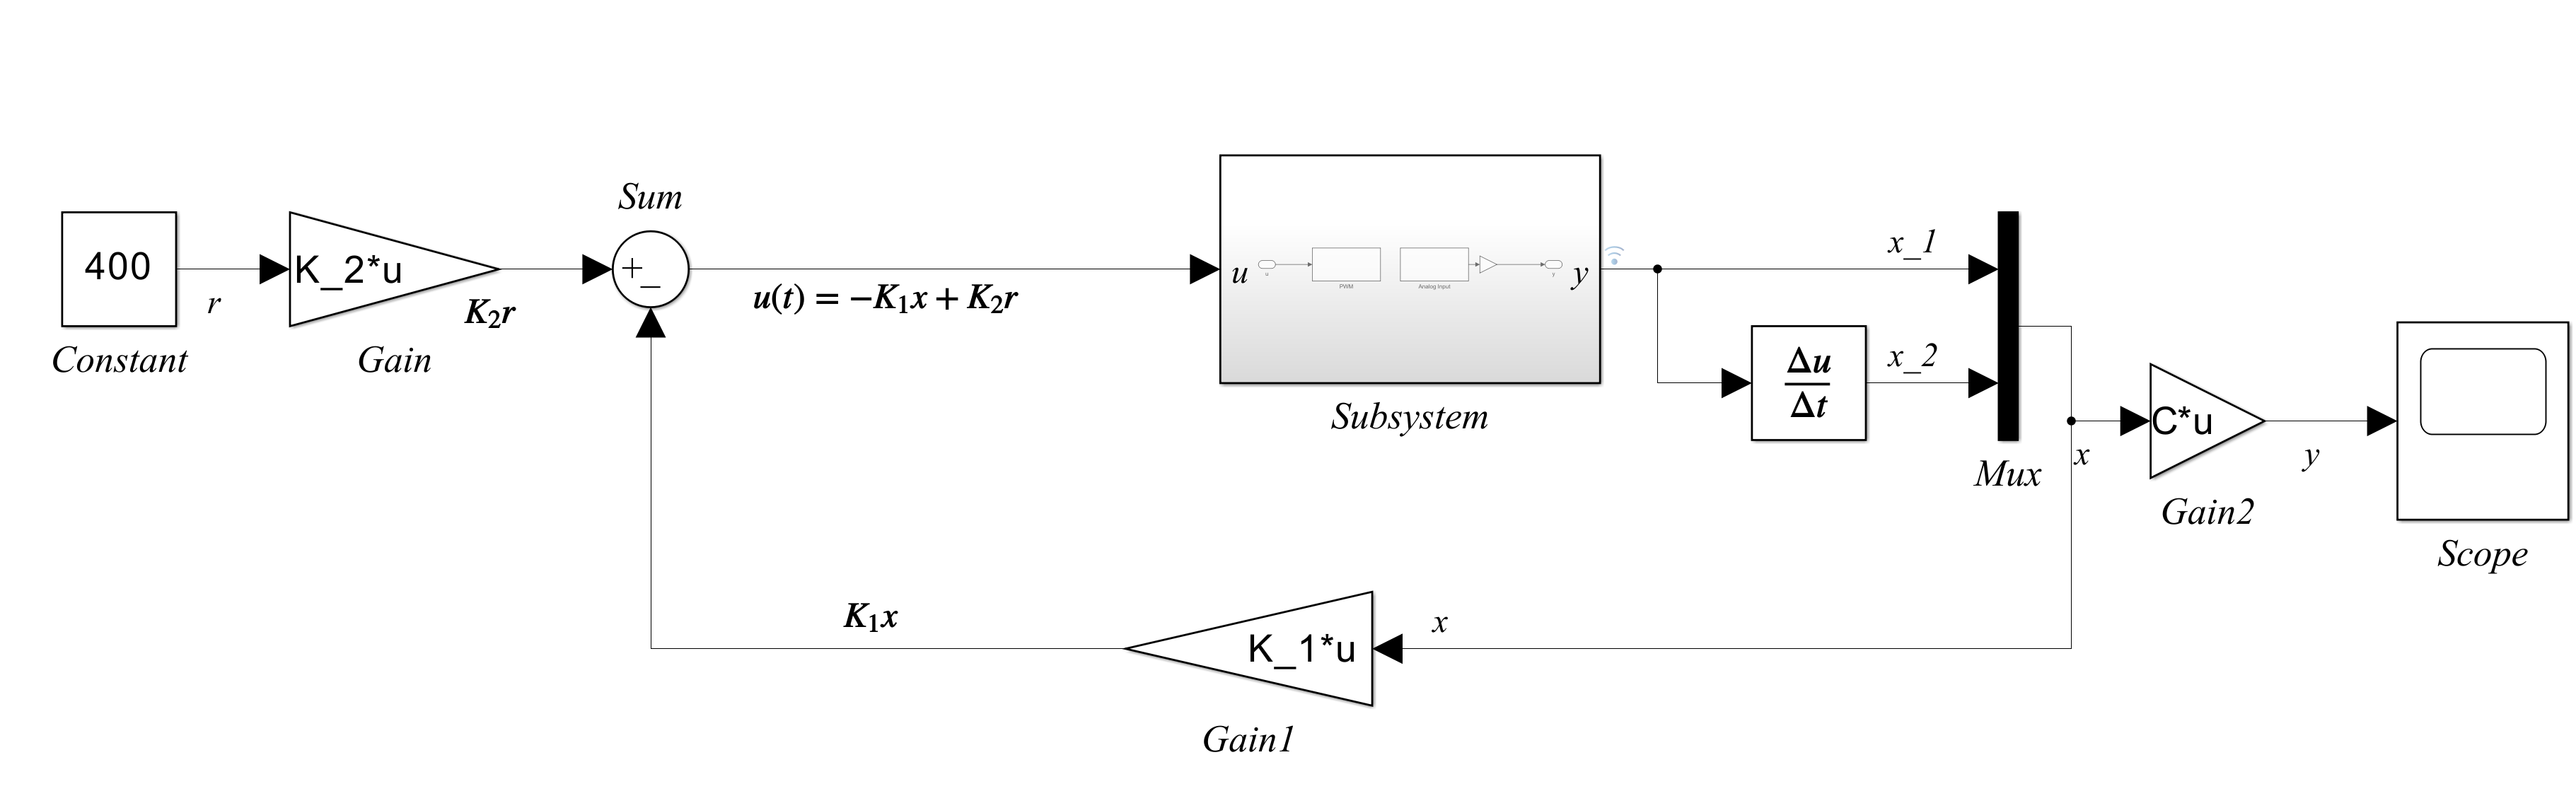

## State Observer

In the experiment we only have a single sensor that measures the output intensity in intesity control or RPM in speed control system. To measure the other states like rate of change in intesity, position or acceleration we can use the observer. The observer can be designed to pridicted the internal states of the system with the output and input signals.